# sic 

#  ENN543 Week 10, Example 2 - Network Training

There are a lot of options to set when training networks, let's look at some.

## Too Long; Didn't Read:

The main take home messages from this example are:

- If in doubt, use the defaults. They work pretty well for most things

- The number of epochs controls how long training runs for. Generally, training for longer is better, however networks do converge after a while, and there is no point keeping training after that

- The batch size controls how many inputs are shown to the network at once. Bigger batches take more time to process and use more memory, but can make a better update becuase they know more about the overall data distribution (though small details can be get lost). Small batches mean more updates per epoch, which can help networks train faster, but can also cause instability.

- Learning rate conrols how fast the most updates. Faster updates get us to the end result quicker, but can make training less stable. By default, learning rate will decrease as the network trains, this is a good thing to do.

- The optimiser is what actually trains the network. All optimisers are based on gradient descent. Some (SGDM and Adam) have momentum which means that part of the update at the current timestep comes from the previous timestep. This can help avoid getting stuck in local minima. Some (RMSProp and Adam) vary the learning rate for each parameter based on it's gradient, which generally helps learning go quicker. In general, all optimisers will perform pretty similarly, but Adam will get you to the end result a bit quicker.

- If in doubt, use the defaults.

## Data Setup

We're using Fastion-MNIST again, data prep is much the same as last time.

filelist = dir('H:\New folder (9)\ENN543_Assignment2_Data\Q2\UTKFace\UTKFace\*.jpg');
targetsize = 64;
images = zeros(targetsize,targetsize,1,length(filelist));
ages = zeros(length(filelist),1);
gender = zeros(length(filelist),1);
race = zeros(length(filelist),1);

for i=1:length(filelist)
    imgs = imresize(rgb2gray(imread(strcat(filelist(i).folder, "/", filelist(i).name))), [targetsize, targetsize]);
    images(:,:,:,i) = imgs;
    values = split(filelist(i).name, '_');
    ages(i) = double(string(values(1)));
    gender(i) = double(string(values(2)));
    race(i) = double(string(values(3)));
end

rng(4);
idx=randsample(1:length(ages),round(length(ages)*0.8),'false');


ages_stupid=categorical(ages);
ages_train=ages_stupid(idx);
ages_test=ages_stupid

ages_test = 23708×1 categorical array
     100 
     100 
     100 
     100 
     100 
     100 
     100 
     100 
     100 
     100 
     100 
     101 
     101 
     103 
     105 
     105 
     105 
     105 
     105 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10 
     10

ages_test(idx)=[];
images_train=images(:,:,:,idx);
images_test=images;
images_test(:,:,:,idx)=[];

## Our Network: A Simple Deep Convoluational Neural Network

We'll use our first DCNN from the previous example. In this case, we're most interested in playing with training parameters, so we'll use this network and play with the training parameters.

layers = [
    imageInputLayer([64 64 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(104)
    softmaxLayer
    classificationLayer];

These are the deafault training options. We'll use these first and then play with them below.

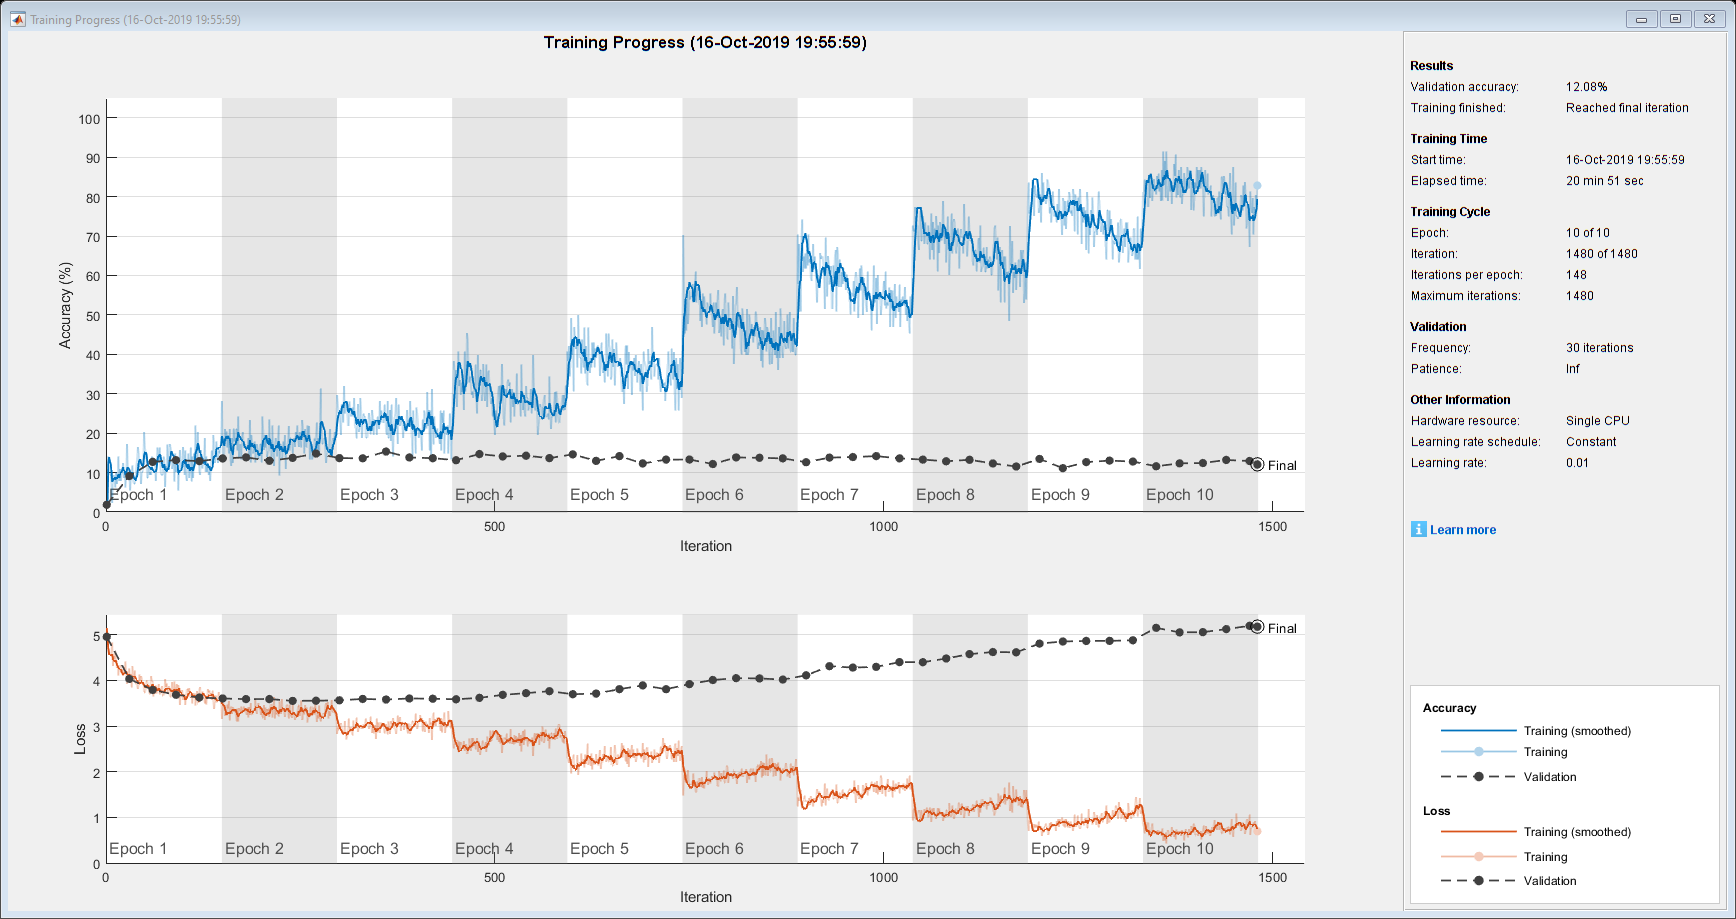

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 128, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(images_train,ages_train, layers, options);

## Optimisers

One of our big choices is the optimiser we use. We have three options in matlab:

- Stochastic Gradient Descent with Momentum (sgdm): the default, will follow the gradient downhill. Uses mometum to smooth the updates and avoid osciliations, such that the update at the current timestep is a result of the current gradient and some amount of the previous

- RMSProp: SGDM has one learning rate for everything, RMSProp allows the learning rate to vary per parameter. Parameters with a very steep gradient have a slower learning rate (as they'll change fast anyway), and those with a shallow gradient have a higher learning rate (to try shift them)

- Adam: or Adaptive Moment Estimation. Can essentially be seen as RMSProp with momentum.

Each of these have parameters you can tune as well, but the default values work well for the majority of problems, and you won't get huge gains by tuning things either, so we'll leave them as is.

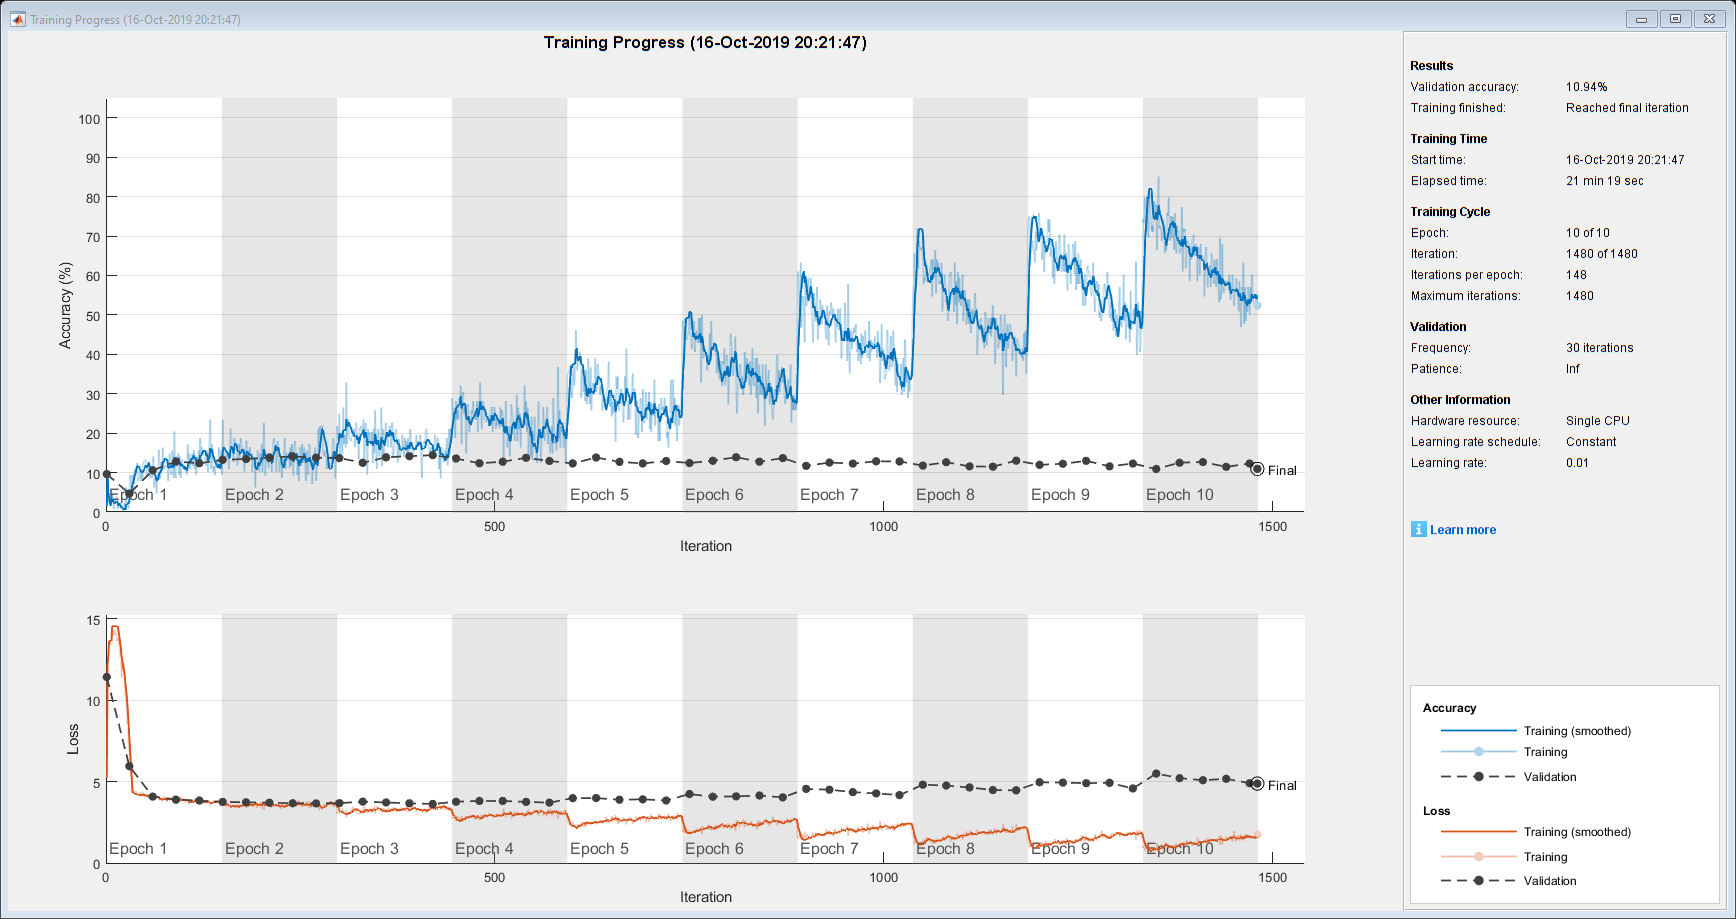

options = trainingOptions('adam', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 128, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(images_train, ages_train, layers, options);

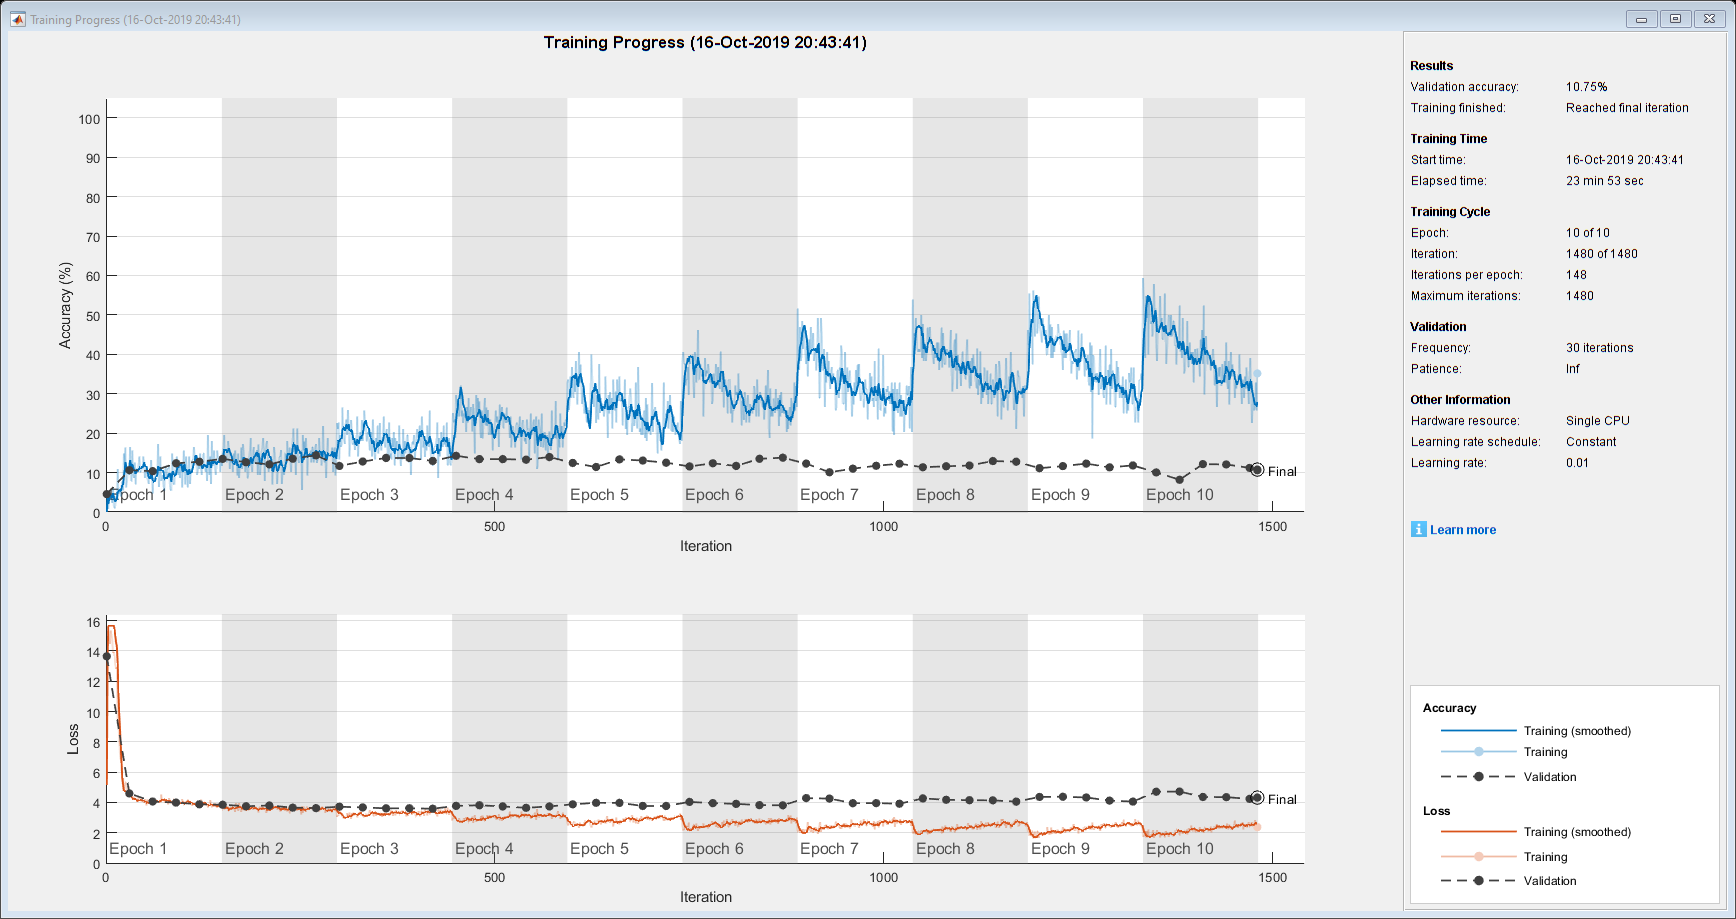

options = trainingOptions('rmsprop', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 128, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(images_train, ages_train, layers, options);

From the above, we see no big difference. Generally (and if you squint you might see this). RMSProp and Adam will learn a bit quicker, and Adam is generaly a bit more stable than RMSProp due to momentum. For this subject, all of these will be fine, but Adam is often the better choice owing to the ability to vary the learning rate per parameter while still having momentum.

## Learning Rate

The learning rate controls how fast things are updated. A very fast learning rate will change quickly, but the network can "overshoot" the optimum result. Too slow a leanring rate and you'll be waiting forever. We also can have a learning rate schedule such that the learning rate decays over time, or by default the learning rate will drop every 10 epochs. Again, the defaults are good in this case, but it doesn't hurt to have a look at learning rate and what can happen.

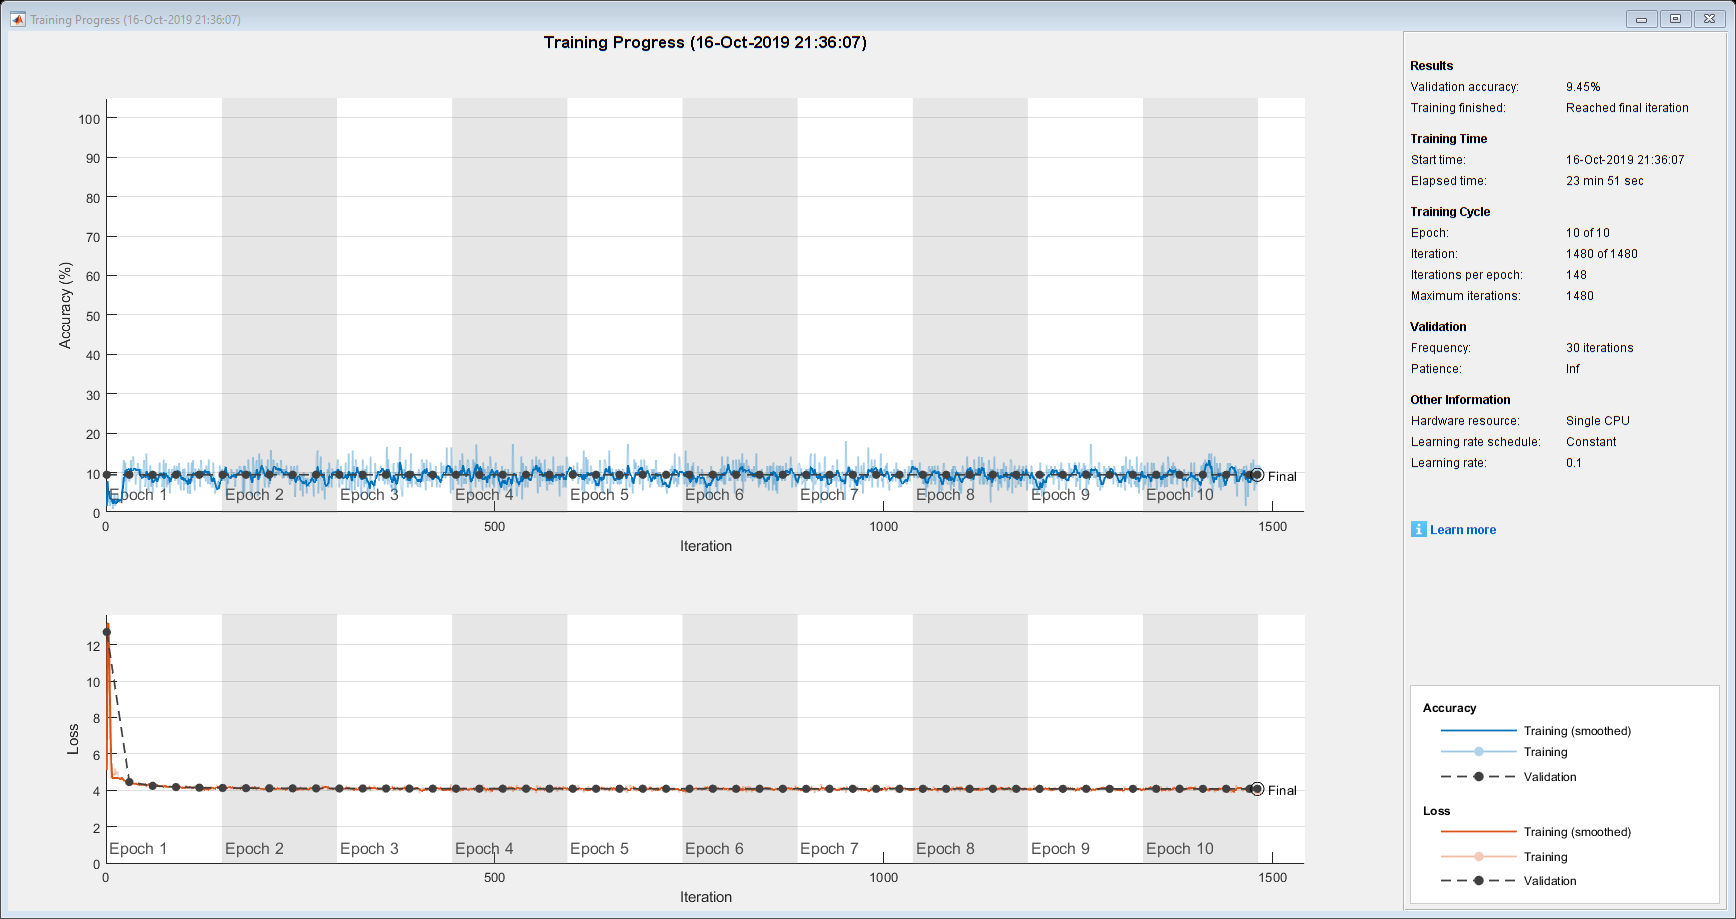

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.1, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 128, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(images_train, ages_train, layers, options);

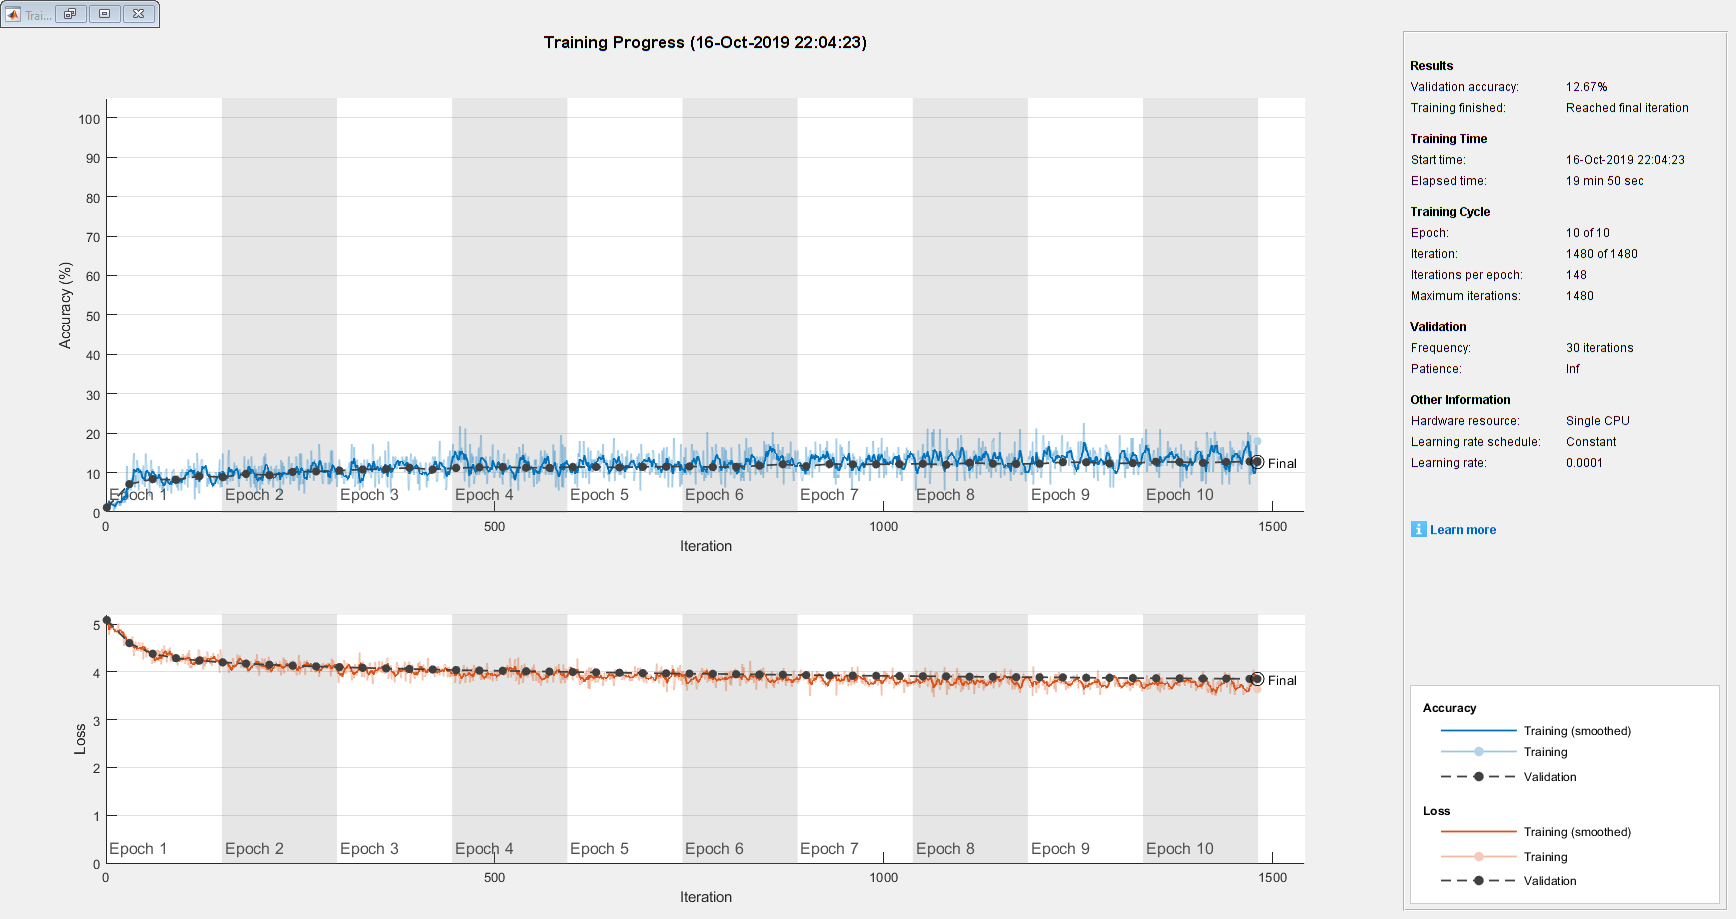

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.0001, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 128, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(images_train, ages_train, layers, options);

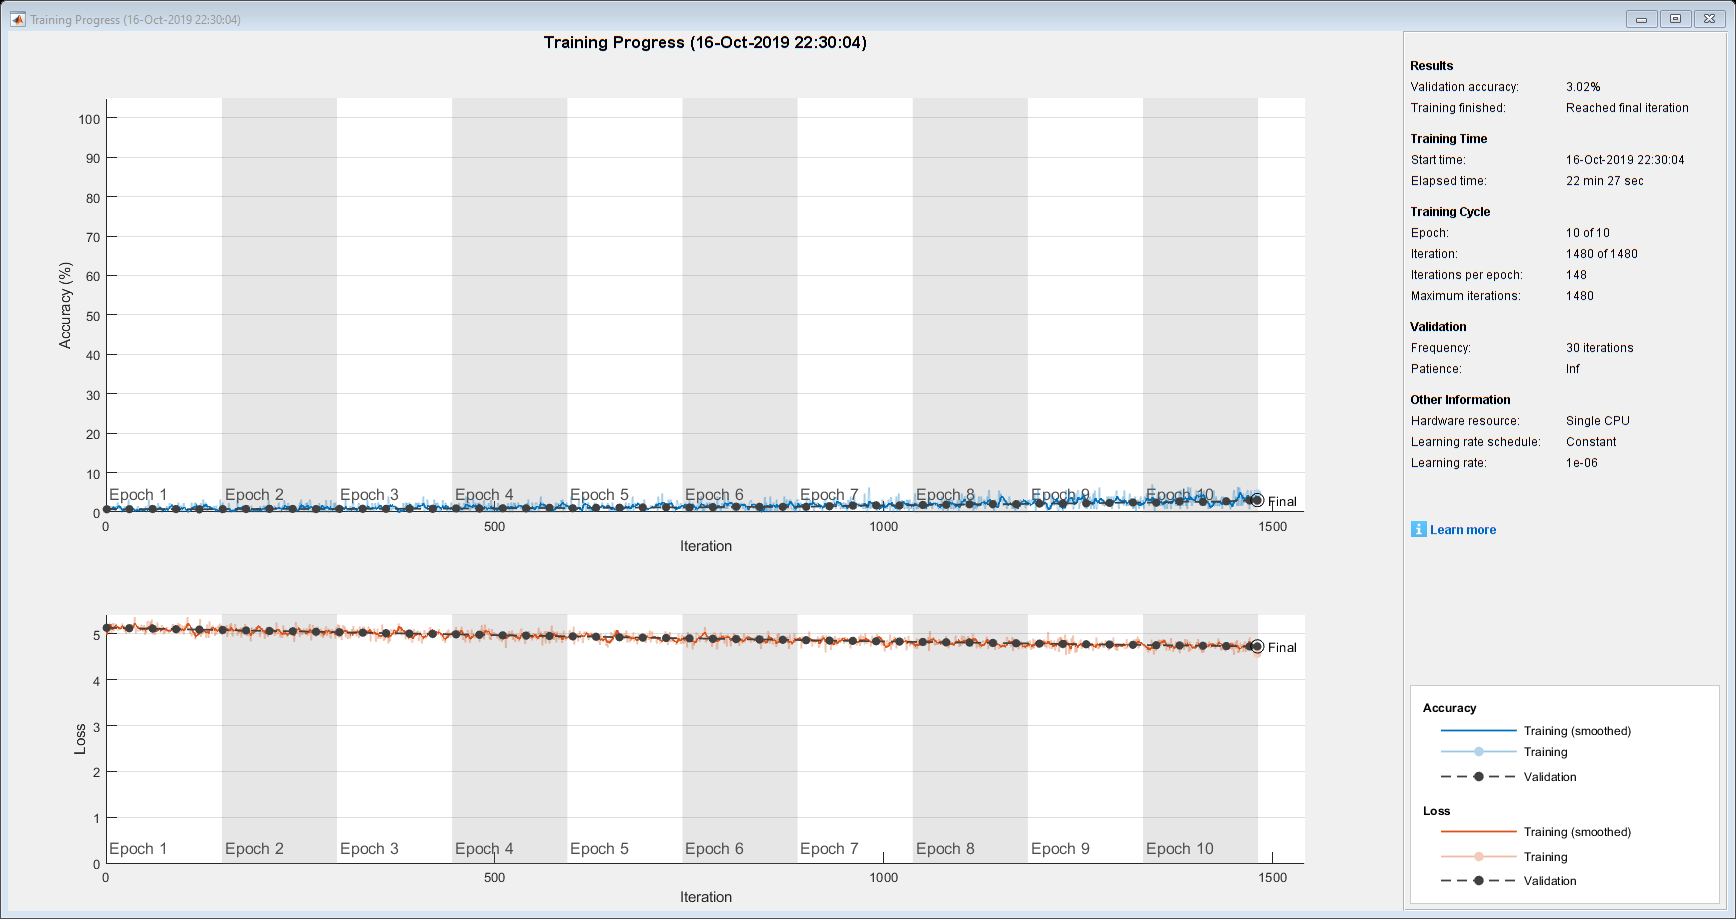

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.000001, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 128, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(images_train, ages_train, layers, options);

What we see if not terribly surprsing:

- With a fast learning rate, the model reaches it's peak quicker, but the plot is rougher, with more variation

- Slower learning rates result in smoother plots and more gradual improvement, but this improvement can be too gradual in the case of our final learning rate.

## Batch Size

Let's try differnet batch sizes now. We'll try

- 4

- 16

- 64

- 256

- 1024

The default is 128. At a batch size of 4, we'll do 32x more gradient descent updates per epoch than with a batch size of 128. If we have limited data, this is one way to give our model an extra chance to learn.

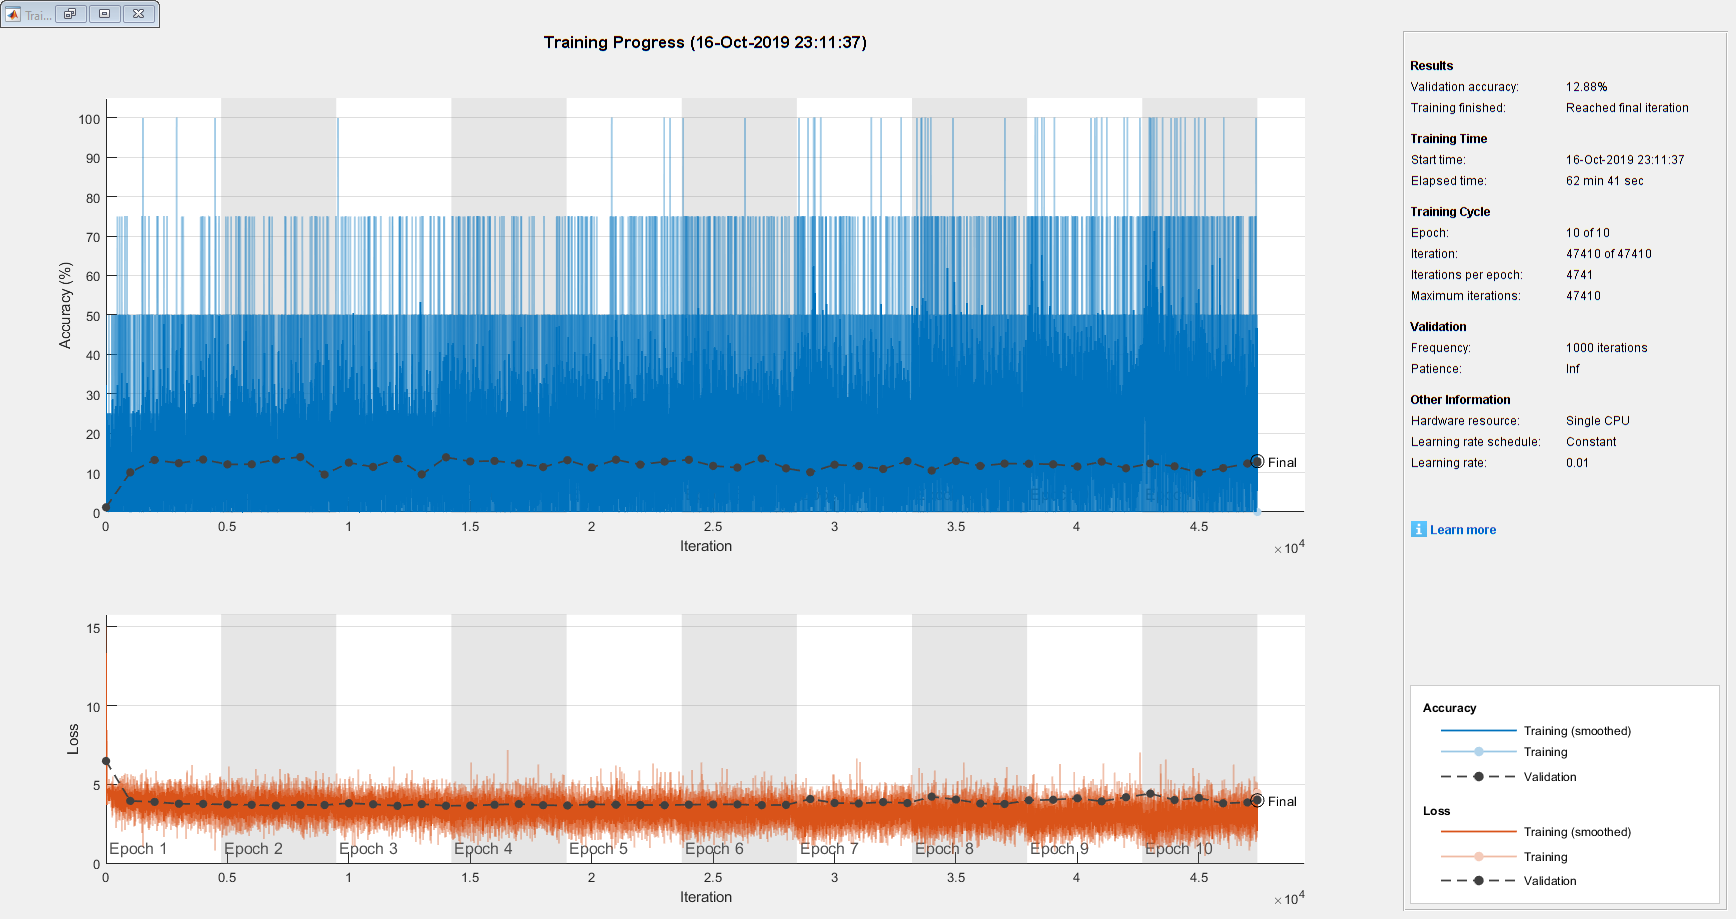

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',1000, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(images_train, ages_train, layers, options);

Our graph is hard to read - there is a lot going on, but we can see that our model takes a long time to train simply because of all the gradient descent passes. 

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 16, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',250, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(images_train, ages_train, layers, options);

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 64, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',60, ...
    'Verbose',false, ...
    'Plots','training-progress');

Undefined function or variable 'images_tests'.

net = trainNetwork(images_train, ages_train, layers, options);

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 256, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',15, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(images_train, ages_train, layers, options);

As the batch size increases, the training profile becomes a lot more stable. With bigger batches each batch is much more representitive of the overall data distribution, so there are fewer surprising results.

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 1024, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{images_test, ages_test}, ...
    'ValidationFrequency',8, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(images_train, ages_train, layers, options);

For our larger batch size we see a very smooth trainig curve, but performance is actually slightly lower, our model most likely hasn't converged yet. While it's seen the same amount of data, it's made less model updates. This version has also trained much faster, but for larger tasks such a large batch size wouldn't be possible. Batch size is usually limited by network size and the amount of memory you have on your system. In this case, we have a small network with small format data, so we can get away with a large batch size.